This scrip try to plot saved MSD data.

V2 we plot both simulation data and exp data

timestep=100;
simu_number=1000;
totel_length=100;
head_index=1;
tail_index=100;

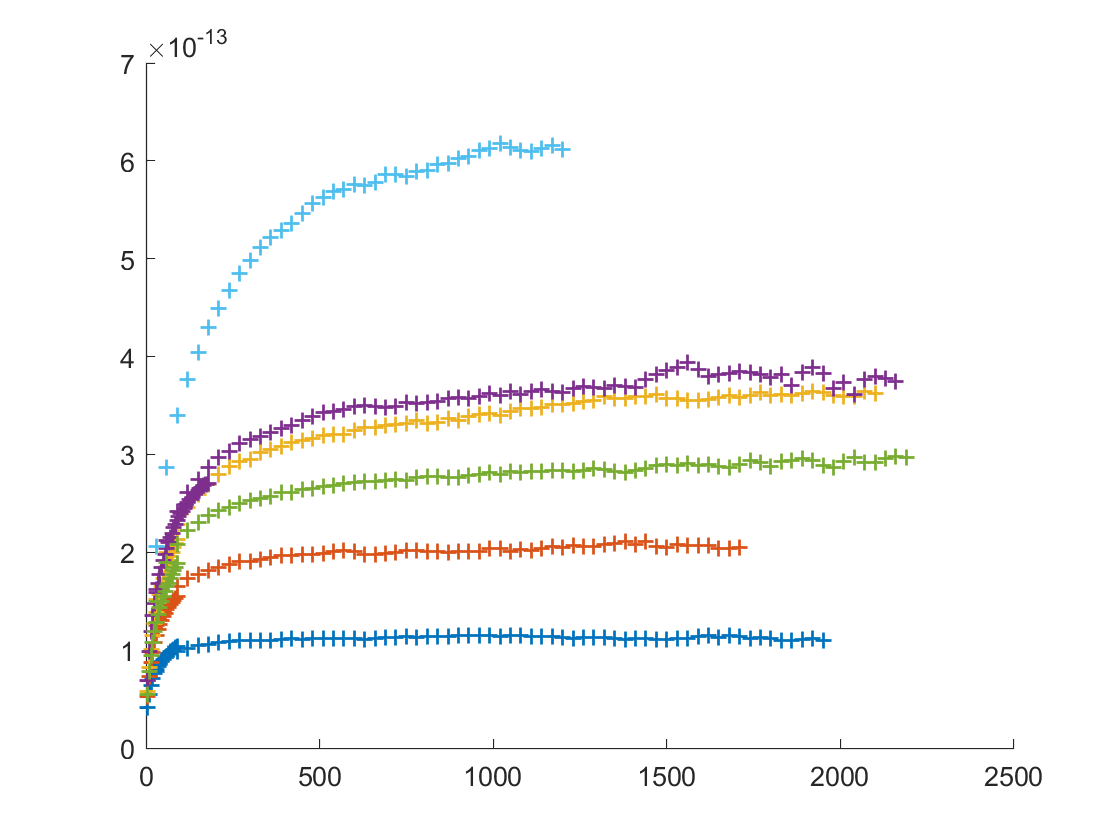

figure
hold on
epDistance_list=[47,77,179];
pnValue='p';
for epDistance=epDistance_list
    expMSDName=[pnValue,num2str(epDistance)];
    expMSDType=[pnValue,num2str(epDistance),' 0.05DifferenceDiscard'];
    load(['C:\Users\zhouquan\OneDrive\research\polychrom simulation\newProcessedData\mixed data ',expMSDType,'.mat']);
    t_exp=t_mixMSD(1,:);
    MSD_exp=t_mixMSD(2,:);
    plot(t_exp,MSD_exp*1e-18,'+','LineWidth',1,'DisplayName',['expMSD',pnValue,num2str(epDistance)])
end
epDistance_list=[78,142,589];
pnValue='n';
for epDistance=epDistance_list
    expMSDName=[pnValue,num2str(epDistance)];
    expMSDType=[pnValue,num2str(epDistance),' 0.05DifferenceDiscard'];
    load(['C:\Users\zhouquan\OneDrive\research\polychrom simulation\newProcessedData\mixed data ',expMSDType,'.mat']);
    t_exp=t_mixMSD(1,:);
    MSD_exp=t_mixMSD(2,:);
    plot(t_exp,MSD_exp*1e-18,'+','LineWidth',1,'DisplayName',['expMSD',pnValue,num2str(epDistance)])
end

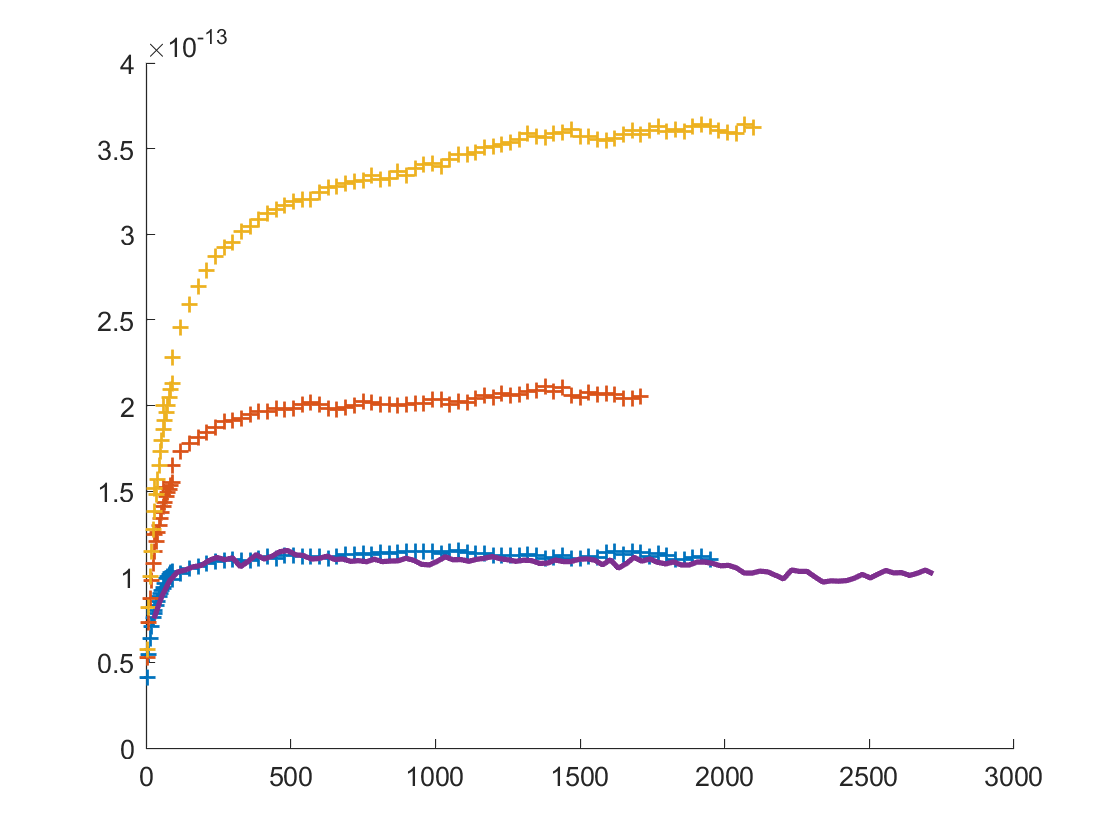

disp1='a=2, k=0.29';
epDistance=47;
b_min=317;
MSDmultiplier=1e-18*(340*epDistance/100)^2;
plot(average_time_list(1,:)/b_min,MSDmultiplier*MSD_average,"LineWidth",2,'DisplayName',disp1)

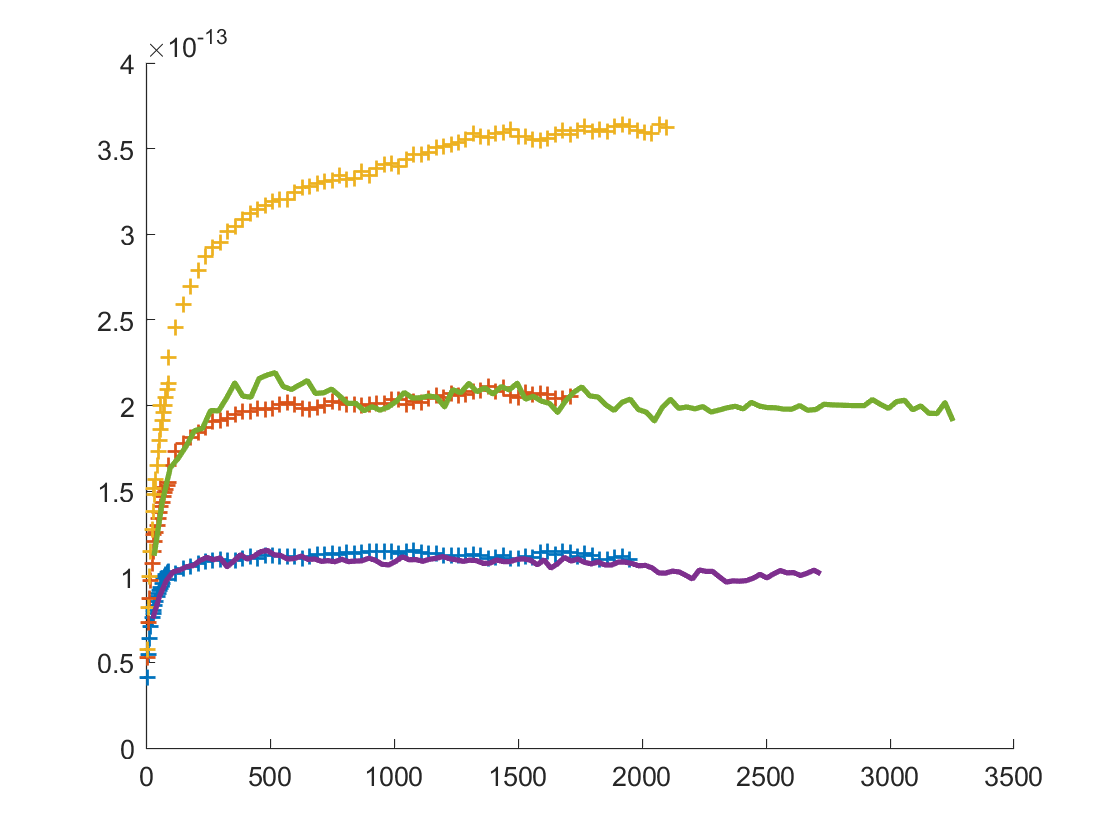

disp2='a=1.27,k=0.40';
epDistance=77;
b_min=265;
MSDmultiplier=1e-18*(340*epDistance/100)^2;
plot(average_time_list(1,:)/b_min,MSDmultiplier*MSD_average,"LineWidth",2,'DisplayName',disp2)

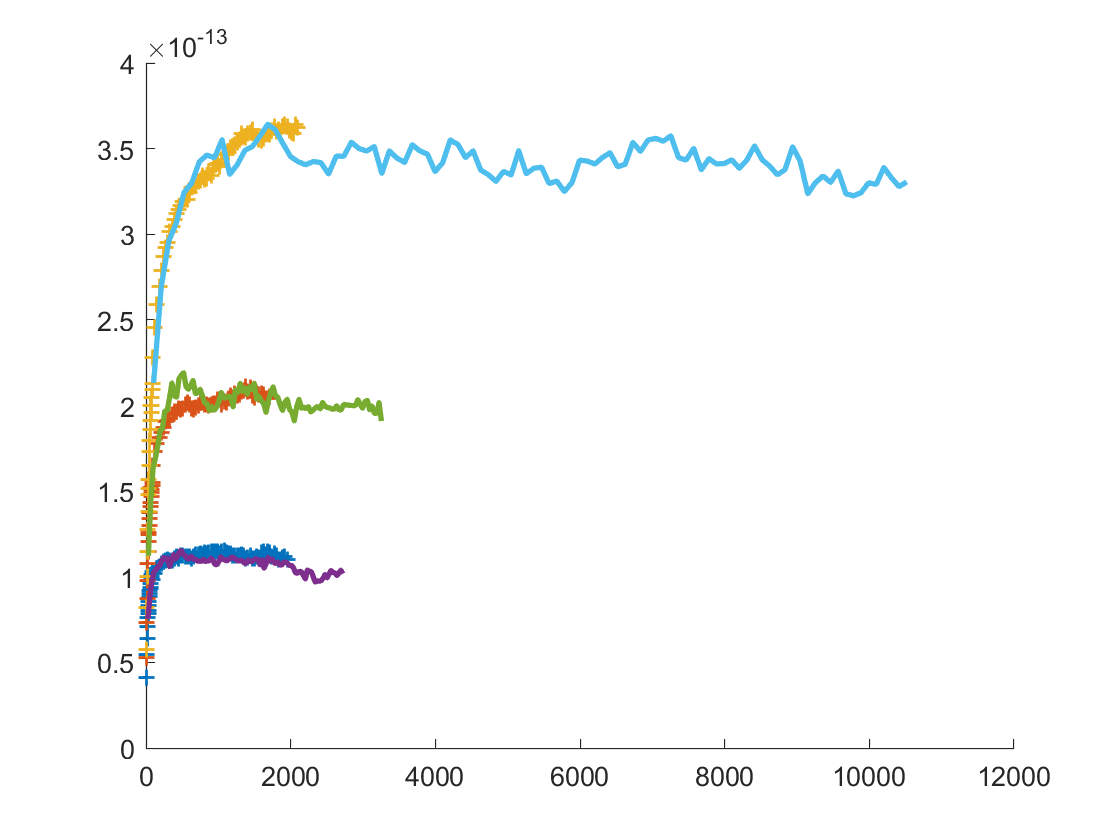

disp3='k=0.63,k=1.35';
epDistance=179;
b_min=41;
MSDmultiplier=1e-18*(340*epDistance/100)^2;
plot(average_time_list(1,:)/b_min,MSDmultiplier*MSD_average,"LineWidth",2,'DisplayName',disp3)

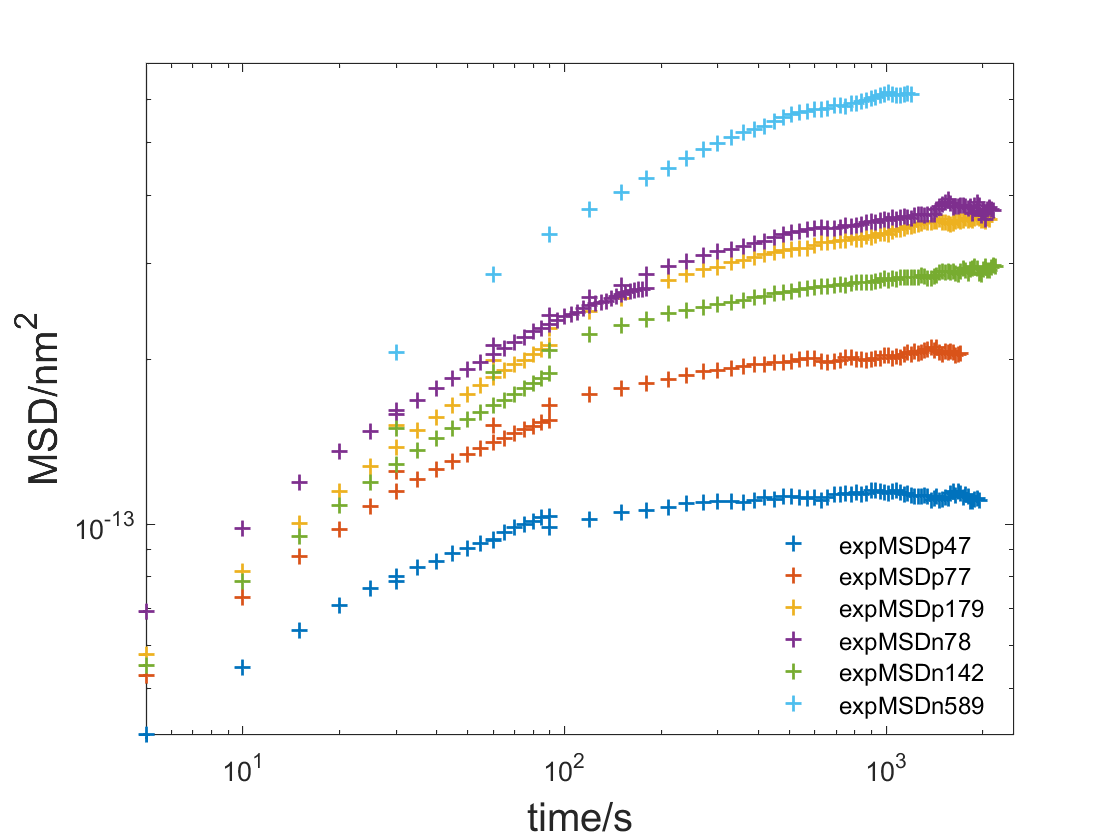

%force_field=['V1=1000(r-a),V2=k\cdot(re-rp)^2'];
force_field=['V1=1000(r-a),V2=k\cdot r_n^2, n=',num2str(head_index),', ',num2str(tail_index)];
%force_field=['$$V(x,y,z)=\left\{\begin{array}{lr}(5\sqrt{x^2+y^2+z^2}-R),&r\geq R \\0,&r<R\end{array}\right.$$n=',num2str(head_index),', ',num2str(tail_index)];
legend("Location","best");
legend('boxoff')
xlabel('time/s',"FontSize",15)
ylabel('MSD/nm^2',"FontSize",15)
set(gca,'yscale','log')
set(gca,'xscale','log')
xlim([0 2.5e3]);
ylim([0 7e-13]);
box on

%title({force_field;''},"FontSize",20)
%title({'Comparing openMM & polychrom Coarse-grained simulation & experiment Data';[' N_e= ',num2str(simu_number)];force_field},"fontsize",18)